# **Dinámica de sistemas físicos**

## Modelado en el dominio de la frecuencia

Dr. Jesús Emmanuel Solís Pérez

jsolisp@unam.mx

### Respuesta en frecuencia

Considere un sistema lineal invariante en el tiempo (LTI) cuya función de transferencia es $G(s)$ y la entrada así como la salida se representan por $x(t)$, $y(t)$ respectivamente. Dicha función se puede escribir como el cociente de dos polinomios en $s$, esto es


$$  G(s) = \frac{p(s)}{q(s)} = \frac{p(s)}{(s+s_{1})(s+s_{2})\cdots(s+s_{n})},$$


o bien


$$G(s) = \frac{b_{n}s^{n} + \cdots + b_{3}s^{3} + b_{2}s^{2} + b_{1}s + b_{0}}{a_{n}s^{n} + \cdots + a_{3}s^{3} + a_{2}s^{2} + a_{1}s + a_{0}}.$$


La transformada de Laplace de la salida $Y(s)$ es


$$Y(s) = G(s)X(s) = \frac{p(s)}{q(s)}X(s)$$


donde $X(s)$ es la transformada de Laplace de la entrada $x(t)$.

La respuesta en estado estacionario de un sistema estable LTI a una entrada sinusoidal no depende de las condiciones iniciales. Considerando que $Y(s)$ tiene  únicamente polos distintos (simples), la ecuación anterior se puede representar en fracciones parciales como sigue:


$$Y(s) = G(s)X(s) = G(s) \frac{\omega X}{s^{2} + \omega^{2}},$$



$$Y(s) = \frac{a}{s + j\omega} + \frac{\bar{a}}{s - j\omega} + \frac{b_{1}}{s + s_{1}} + \frac{b_{2}}{s + s_{2}} + \dots + \frac{b_{n}}{s + s_{n}}.$$


donde $a$ y $b_{i}, i=1,2,\dots,n$ son constantes y $\bar{a}$ es el complejo conjugado de $a$.

Por tanto, aplicando la transformada inversa de Laplace de la ecuación tenemos


$$y(t) = ae^{-j\omega t} + \bar{a}e^{j\omega t} + b_{1}e^{-s_{1} t} + b_{2}e^{-s_{2} t} + \cdots + b_{n}e^{-s_{n} t}, \quad t\geq 0.$$


### Función de transferencia propia

Considere la siguiente función de transferencia


$$G(s) = \frac{N(s)}{D(s)},$$


donde $N(s)$ y $D(s)$ son dos polinomios con coeficientes reales, entonces tenemos

- Función **impropia** si $\text{deg }N(s) > \text{deg }D(s)$. 

- Función **propia** si $\text{deg }N(s) \leq \text{deg }D(s)$.

- Función **estrictamente propia** si $\text{deg }N(s) < \text{deg }D(s)$.

- Función **bipropia** si $\text{deg }N(s) = \text{deg }D(s)$.

### Polos y zeros

Considere una función de transferencia racional propia


$$G(s) = \frac{N(s)}{D(s)},$$


donde $N(s)$ y $D(s)$ son polinomios con coeficientes reales y $\text{deg} N(s) \leq \text{deg}D(s)$.

***Definción 1.*** Un número complejo o real finito $\lambda$ es un **polo** de $G(s)$ si $|G(s)| = \infty$, donde $|\cdot|$ denota el valor absoluto. Por otro lado, si $G(\lambda)=0$ entonces es un **zero** de $G(s)$.

## Ejemplo 1

Considere la siguiente función de transferencia


$$G(s) = \frac{N(s)}{D(s)} = \frac{2\left( s^{3} + 3s^{2} - s - 3 \right)}{\left( s - 1 \right)\left( s + 2 \right)\left(s + 1 \right)^{3}},$$


obtenga sus polos y zeros.

Del procedimiento anterior concluimos que $G(s)$ tiene un zero en $-3$ y tres polos: $-2$, $-1$ y $-1$. Aquí tenemos:

- El polo $-2$ es llamado polo **simple**.

- El polo $-1$ es llamado polo **repetido** con multiplicidad 3.

% Primera forma
N = [2 6 -2 -6]
ceros = roots(N)

% Segunda forma
syms s
N = 2*s^3 + 6*s^2 - 2*s -6 == 0;

sol = solve(N,s)

$$sol = \left(\begin{array}{c} -3\\ -1\\ 1 \end{array}\right)$$

sol

$$sol = \left(\begin{array}{c} -3\\ -1\\ 1 \end{array}\right)$$


% Tercera forma
s = tf('s');

Ns = 2*s^3 + 6*s^2 -2*s - 6;
Ds = (s-1)*(s+2)*(s+1)^3;

Gs = Ns/Ds

Gs =
 
         2 s^3 + 6 s^2 - 2 s - 6
  -------------------------------------
  s^5 + 4 s^4 + 4 s^3 - 2 s^2 - 5 s - 2
 
Continuous-time transfer function.




pole(Gs)

ans =    1.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


zero(Gs)

ans =    -3.0000
    1.0000
   -1.0000



% Cuarta forma
s = tf('s');

Ns = 2*s^3 + 6*s^2 -2*s - 6;
Ds = (s-1)*(s+2)*(s+1)^3;

Gs = Ns/Ds

Gs =
 
         2 s^3 + 6 s^2 - 2 s - 6
  -------------------------------------
  s^5 + 4 s^4 + 4 s^3 - 2 s^2 - 5 s - 2
 
Continuous-time transfer function.



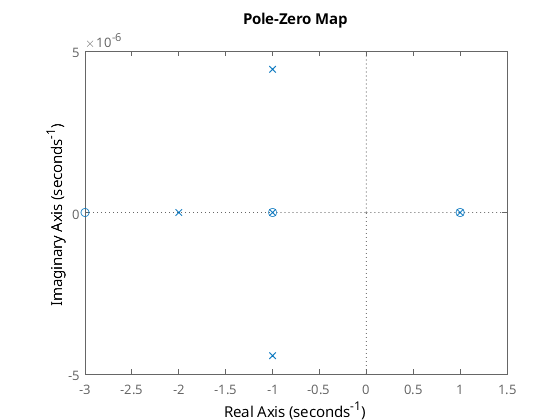


pzmap(Gs)


% Simiplificando una expresión
syms s

Ns = 2*s^3 + 6*s^2 -2*s - 6;
Ds = (s-1)*(s+2)*(s+1)^3;

Gs = simplify(Ns/Ds)

$$Gs = \frac{2\,s+6}{{\left(s+1\right)}^{2}\,\left(s+2\right)}$$

Gs

$$Gs = \frac{2\,s+6}{{\left(s+1\right)}^{2}\,\left(s+2\right)}$$

## Ejemplo 2

Sea $u(t) = 1$ con $t\leq 0$ la respuesta de escalón unitario, calcule la respuesta de estado cero de la siguiente función de transferencia


$$Y(s) = G(s)U(s) = \frac{3s-1}{(s+1)(s+2)}\cdot U(s).$$


Por lo tanto, la respuesta de estado cero en el dominio del tiempo está dada como sigue:


$$y(t) = \underbrace{4e^{-t} - 3.5e^{-2t}}_{\text{polos de } G(s)} - \underbrace{0.5}_{\text{polo de } U(s)}.$$


### **Estabilidad de sistemas**

- **Sistema Absolutamente Estable:** todos los polos del sistema estén estrictamente en el semi-plano izquierdo, sin importar la multiplicidad.

- **Sistema Marginalmente Estable:** al menos un polo está sobre el eje imaginario con multiplicidad uno y el resto están estrictamente en el semi-plano izquierdo, sin importar la multiplicidad.

-  **Sistema Inestable:** al menos un polo está sobre el eje imaginario con multiplicidad mayor a uno o en el semiplano derecho.

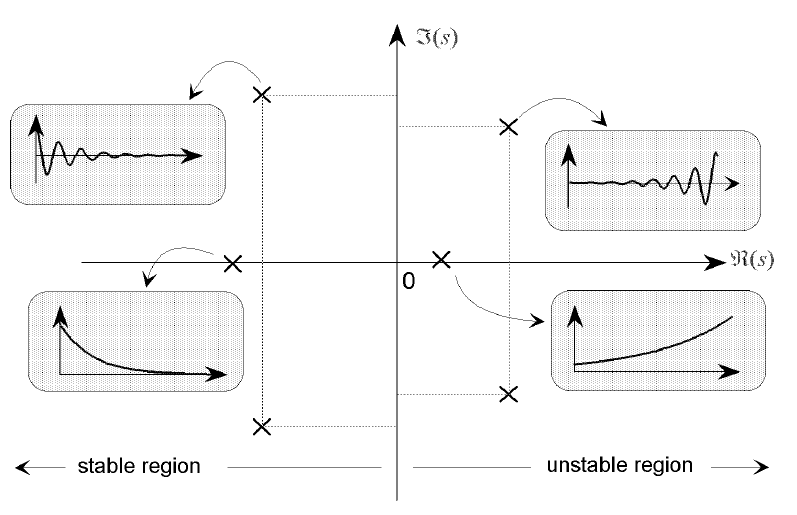

### Polinomio de Hurwitz

***Definición 2.*** Un polinomio con coeficientes reales es llamado polinomio de **Hurwitz **si todas sus raíces tienen partes reales negativas. 

Considere el siguiente polinomio


$$D(s) = a_{n}s^{n} + a_{n-1}s^{n-1} + \dots + a_{1}s + a_{0}, \quad a_{n}>0,$$


donde $a_{i},i=0,1,\dots,n$ son constantes reales.

### Condiciones necesarias

- Si $D(s)$ es Hurwitz, entonces todos los coeficientes de $D(s)$ deben ser positivos.

- Si $D(s)$ tiene un término perdido o un coeficiente cero, entonces no es Hurwitz.

***Teorema 1.*** Un polinomio con coeficientes positivos es un polinomio Hurwitz si y sólo si cada entrada en la tabla Routh es positivo, o equivalentemente, si y sólo si cada entrada en la primer columna de la tabla ($b_{61},b_{51},b_{41},b_{31},b_{21},b_{11},b_{01}$) es positivo.

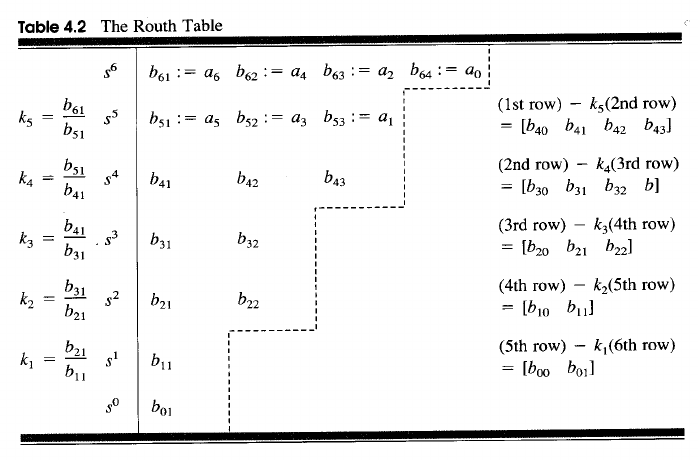

## Ejemplo 3

Considere el siguiente polinomio


$$2s^{4} + s^{3} + 5s^{2} + 3s + 4.$$


Determine si el sistema es estable o no estable utilizando el método de Routh-Hurwitz.

## Ejemplo 4

Considere el siguiente polinomio


$$2s^{5} + s^{4} + 7s^{3} + 3s^{2} + 4s + 2.$$


Determine si el sistema es estable o no estable utilizando el método de Routh-Hurwitz.

## Ejemplo 5

Considere el siguiente polinomio


$$2s^{5} + s^{4} + 7s^{3} + 3s^{2} + 4s + 1.5.$$


Determine si el sistema es estable o no estable utilizando el método de Routh-Hurwitz.

## Ejemplo 6

Considere la siguiente función de transferencia


$$G_{o}(s) = \frac{(2s + 1)(s + 1)}{s^{5} + 5s^{4} + 12s^{3} + 14s^{2} + 3s + 1}.$$


Determine si el sistema es estable o no estable utilizando:

- Polos y zeros.

- El método de Routh-Hurwitz.

s = tf('s');

num = (2*s + 1)*(s + 1);
den = s^5 + 5*s^4 + 12*s^3 + 14*s^2 + 3*s + 1;

Gs = num/den

Gs =
 
              2 s^2 + 3 s + 1
  ---------------------------------------
  s^5 + 5 s^4 + 12 s^3 + 14 s^2 + 3 s + 1
 
Continuous-time transfer function.



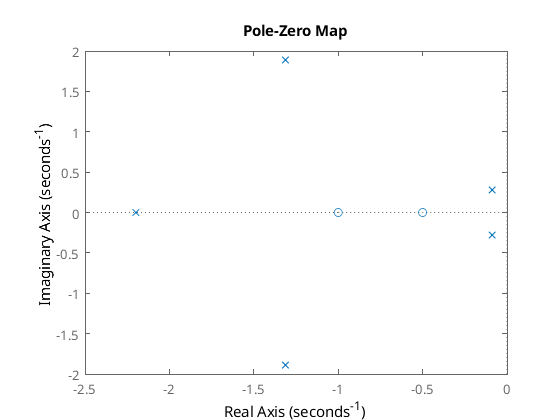


pzmap(Gs)

## Ejemplo 7

Considere la siguiente función de transferencia

s = tf('s');
k = 1; % -1/4 < k < 5/4
Gs = (8*k)/((s + 1)*(s^2 + 2*s + 2) + 8*k)

Gs =
 
            8
  ----------------------
  s^3 + 3 s^2 + 4 s + 10
 
Continuous-time transfer function.



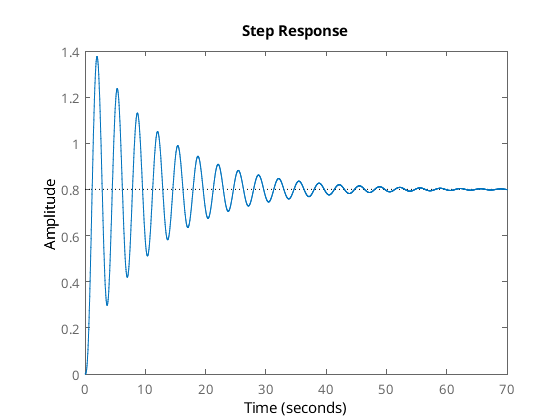


step(Gs)


pzmap(Gs)

pole(Gs)

ans =   -2.8338 + 0.0000i
  -0.0831 + 1.8767i
  -0.0831 - 1.8767i



help step

 step  Step response of dynamic systems.
 
    [Y,T] = step(SYS) computes the step response Y of the dynamic system SYS. 
    The time vector T is expressed in the time units of SYS and the time 
    step and final time are chosen automatically. For multi-input systems,
    independent step commands are applied to each input channel. If SYS has 
    NY outputs and NU inputs, Y is an array of size [LENGTH(T) NY NU] where 
    Y(:,:,j) contains the step response of the j-th input channel.
 
    For state-space models, 
       [Y,T,X] = step(SYS) 
    also returns the state trajectory X, an array of size [LENGTH(T) NX NU] 
    for a system with NX states and NU inputs.
 
    For identified models (see IDMODEL),
       [Y,T,X,YSD] = step(SYS) 
    also computes the standard deviation YSD of the response Y (YSD is empty 
    if SYS does not contain parameter covariance information).
 
    [Y,...] = step(SYS


$$G_{o}(s) = \frac{8k}{(s + 1)(s^{2} + 2s + 2) + 8k},$$
 

Determine si el sistema es estable o no estable utilizando:

- El método de Routh-Hurwitz.

## Ejemplo 8

Determine el intervalo de estabilidad para el siguiente sistema:


$$G
(s) = \frac{k(s^{2} - 2s + 5)}{s^{3} + (5 + k)s^{2} + (12 - 2k)s + 5k - 18}.$$


Utilice el criterio de Routh-Hurwitz para resolver este ejercicio.